# Figure S1C

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'E2000_data.mat'],'S');


%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'siCtrl',2:7,2,1; %1      
    'siCDC6',2:7,3,1; %1
    'siCDC6/CDT1',2:7,4,1; %1
    'siCDT1',2:7,5,1; %1
    'siFZR1',2:7,6,1; %1
    'siFBXO5',2:7,7,1; %1
};

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart =0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    
end

Proportion apc vs proportion s overlap

conds = [1];
figure('units','inches','position',[0 0 4 4]), hold on

POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
    inds = ~isnan(S(conds(i)).POI(:,POI_align))&...
        S(conds(i)).POI(:,1) <= 20& S(conds(i)).POI(:,1)>=0 ;
 
    mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
     hold on
    plot(x,f,'LineWidth',2,'LineStyle','-','color',[.2 .6 .9]);
  sum(inds)


   POI_cal = 2;

    mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
hold on

    plot(x,f,'LineWidth',2,'LineStyle','--','Color',[.8 .1 .2]);
     
end

ans = 397

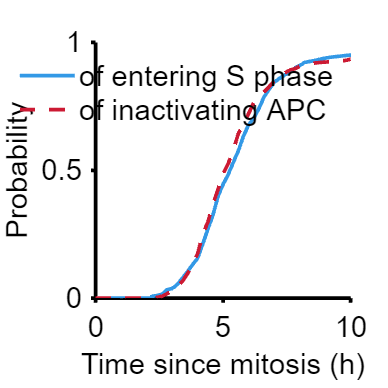

set(gca,'fontsize',16,'linewidth',2)
legend ('of entering S phase','of inactivating APC','box','off','fontsize',16)
xlim([0 10])
ylim ([0 1])
yticks(0:.5:1)
xlabel('Time since mitosis (h)')
ylabel('Probability')
axis square

% print_pdf(['fig_S1C.pdf'])

CRL activation post mitosis

conds=[1 6];
timeGate = [0 20];
cols =  [0 0 .5;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];;

figure('unit','inches','position',[0 0 4 8])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) & S(conds(i)).POI(:,1) < 50;
   
     mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);

    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    
   plot(x,f, 'Color',cols(i,:));
 
    sum(inds)
end

ans = 1010

ans = 764



axis square
legend('Control','siEmi1','Box','off','Location','southeast','FontSize',16);
xlim([0 10]); 
xticks(0:5:20)
ylim([0 1]);
set(gca,'fontsize',16, 'linewidth',2)
xlabel('Time since mitosis (h)')
ylabel('Probability of cells in S phase')
hold on


APC inactivation post mitosis


nexttile

hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
    
      
  
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) & S(conds(i)).POI(:,1) < 50 ;%& S(conds(i)).apcGate;

    mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    plot(x,f, 'Color',cols(i,:));
    sum(inds)
end

ans = 1010

ans = 764

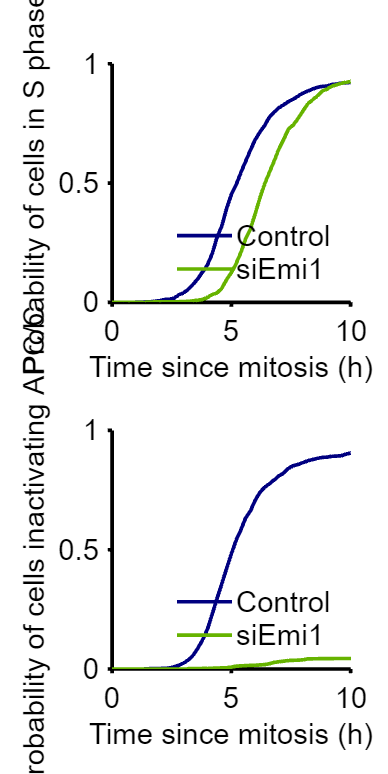



axis square
legend('Control','siEmi1','Box','off','Location','southeast','FontSize',16);
set(gca,'fontsize',16, 'linewidth',2)
xlim([0 10]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time since mitosis (h)')
ylabel('Probability of cells inactivating APC/C')

% print_pdf(['fig_S1j.pdf'])

%Scatter CD
conds=[1];
timeGate = [0 20];
colors =  [0 0 .99;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];;

POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
        data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) ;%&...
        % data.apcExpressGate & data.goodCdk;
%     ydata = data.cdk(inds,:);
%     POI = data.POI(inds,POI_align);
%     idx = sub2ind(size(ydata),(1:length(POI))',POI);
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 100 & yvals > -100);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    length(yvals)
end

ans = 2255

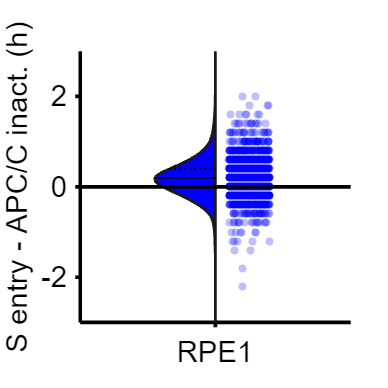

% colors = [.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
cols = repmat({colors(1,:)}',1,1);
groupcol = repmat([colors([1  ],:)],1,1);
figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'S entry - APC/C inact. (h)'])
hline(0,'k')
% xticks([2 5 8 11 14])
% xticklabels(conditions(conds,1))
 xticklabels({'RPE1'})
 ylim([-3 3])
% xtickangle(45)
axis square

% print_pdf(['fig_s1e.pdf'])
